# Lab 5

## Es 3

load("test_functions2.mat", '-mat')

alpha0 = 5;
c1 = 1e-4;
rho = 0.8;
btmax = 50;
[xk, fk, gradfk_norm, k, xseq, eigs] = newton_bcktrck_corrected(x0, f2, gradf2, Hessf2, kmax, tolgrad, c1, rho, btmax)

xk = 1.0e+13 *

   -0.0000
    5.1535


fk = 5.1535e+13

gradfk_norm = 1.4358e+07

k = 1000

xseq = 1.0e+13 *

   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0005    0.0010   -0.0087    0.0155   -0.1381    0.2432   -2.4823    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535    5.1535 

eigs = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0014    0.0008    0.0220    0.0124    0.3471    0.1946    7.1771    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228    4.1228 

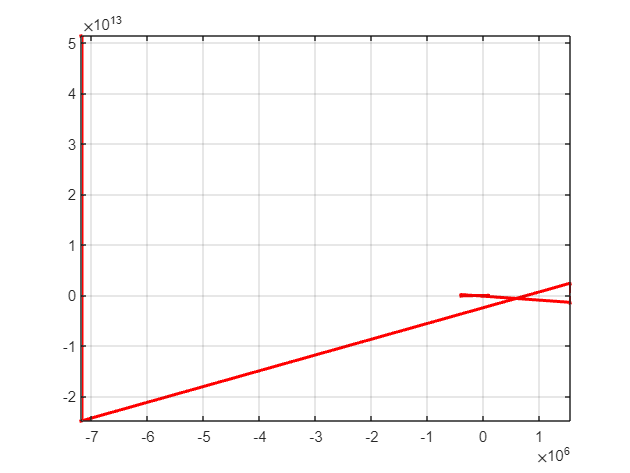

x = linspace(-30, 30, 200);
y = linspace(-40, 30, 200);
[X,Y] = meshgrid(x,y);
% Z = f3(x, y);
Z = 100*(Y-X.^2).^2 + (1-X).^2;
contour(X, Y, Z)
% surf(X,Y,Z)
grid on;
hold on;
h = plot(xseq(1,:), xseq(2,:), '-*r', 'linewidth', 2, 'markersize', 2);

hold off